## **Vectors**


$$$\vec{v} = [x \quad y \quad z]^T$$$


v = [2, 2, 2]'

v =      2
     2
     2


t = [8, 1, 5]'

t =      8
     1
     5


### Vector operations:

- addition

v_plus_t = v + t

v_plus_t =     10
     3
     7


- scaling

t_times_5 = 5 * t

t_times_5 =     40
     5
    25


- dot product

dot_product = dot(v, t)

dot_product = 28

q = [0, 5]'

q =      0
     5


p = [-1, 0]'

p =     -1
     0


perpendicular_vectors = dot(q, p)

perpendicular_vectors = 0

- cross product

cross_product = cross(v ,t)

cross_product =      8
     6
   -14


q = [4, 8, -2]'

q =      4
     8
    -2


p = [1, 2, -1/2]'

p =     1.0000
    2.0000
   -0.5000


parallel_vectors = cross(q, p)

parallel_vectors =      0
     0
     0


- norm

v_norm = norm(v)

v_norm = 3.4641

## **Matrices**

Matrice is a table of numbers

P = [-1 3/2 5; 0 2 -3.5]

P =    -1.0000    1.5000    5.0000
         0    2.0000   -3.5000


R = [7; -3; 0]

R =      7
    -3
     0


S = [1; 2; -1; -3]

S =      1
     2
    -1
    -3


T = [1 2; 3 -2]

T =      1     2
     3    -2


A = [5 2 6; 9 3 2; 5 0 1]

A =      5     2     6
     9     3     2
     5     0     1


B = [2 1 5; 0 0 3; 8 2 2]

B =      2     1     5
     0     0     3
     8     2     2


s = 3

s = 3

### Matrix operations:

####     Addition (subtraction) 

- A and B have to be of the same size

addition = A + B;

####     Scaling

- s(A + B) = sA + sB

- (s + B)A = sA + sB

- (sB)A = s(BA) = B(sA)

scaling = s .* A

scaling =     15     6    18
    27     9     6
    15     0     3


####     Multiplication

- A of m x n dimension, B of s x m dimension, result of n x s

multiplication_nr = P * R

multiplication_nr =   -11.5000
   -6.0000


multiplication_r = A * B

multiplication_r =     58    17    43
    34    13    58
    18     7    27


####     Transposition

- 
$$(A^T)^T = A$$


- 
$$(A+B)^T = A^T + B^T$$


- 
$$(sA)^T = s(A^T)$$


- 
$$(A*B)^T = B^T * A^T$$


transposition = A'

transposition =      5     9     5
     2     3     0
     6     2     1


A

A =      5     2     6
     9     3     2
     5     0     1


(A')'

ans =      5     2     6
     9     3     2
     5     0     1


(A + B)'

ans =      7     9    13
     3     3     2
    11     5     3


A' + B'

ans =      7     9    13
     3     3     2
    11     5     3


(s*A)'

ans =     15    27    15
     6     9     0
    18     6     3


s*(A')

ans =     15    27    15
     6     9     0
    18     6     3


(A*B)'

ans =     58    34    18
    17    13     7
    43    58    27


B' * A'

ans =     58    34    18
    17    13     7
    43    58    27


## Determinants

- det($A^T$) = det(A)

- det(AB) = det(A)det(B)

- det(sA)=${\;s}^n$ det(A)

- if row is all zeros, det(A) = 0

- if two identical rows, det(A) = 0

A = [5 2 6; 9 3 2; 5 0 1]

A =      5     2     6
     9     3     2
     5     0     1


B = [1 2; 2 4]

B =      1     2
     2     4


C = [1 8 -2; 4 6 2; 1 8 -2]

C =      1     8    -2
     4     6     2
     1     8    -2


D = [0 0 0; -2 5 1; 0 5 7]

D =      0     0     0
    -2     5     1
     0     5     7


E = [3 1 1; 5 3 -7; 1 3 4]

E =      3     1     1
     5     3    -7
     1     3     4


s = 2

s = 2

det(A)

ans = -73

det(A')

ans = -73

det(A*E)

ans = -6132

det(A)*det(E)

ans = -6.1320e+03

det(s*A)

ans = -584

det(A)*s^3

ans = -584

det(B)

ans = 0

det(C)

ans = 0

det(D)

ans = 0

### Area of a 2D figure

Can be computed by taking a determinant of two vectors of size 2x1.

v = [3, 0]'

v =      3
     0


t = [0, 3]'

t =      0
     3


area = det([v, t])

area = 9

### Volume of a 3D figure

Can be computed by taking a determinant of three vectors of size 3x1

v = [3, 0, 0]'

v =      3
     0
     0


t = [0, 3, 0]'

t =      0
     3
     0


p = [0, 0, 3]'

p =      0
     0
     3


volume = det([v, t, p])

volume = 27

## Rank

A = [1 1 1 1; 3 8 2 7]

A =      1     1     1     1
     3     8     2     7


B = [1 1 1 1; 3 8 2 7; 2 5 2 1]

B =      1     1     1     1
     3     8     2     7
     2     5     2     1


C = [1 1 1 1; 2 2 2 2; 3 3 3 3]

C =      1     1     1     1
     2     2     2     2
     3     3     3     3


D = [1 5 3; 9 2 8; 0 0 0]

D =      1     5     3
     9     2     8
     0     0     0


E = [0 1 5; 0 -2 4; 0 6 0]

E =      0     1     5
     0    -2     4
     0     6     0


F = [1 2 3; 2 4 3; 4 8 3]

F =      1     2     3
     2     4     3
     4     8     3


rank_A = rank(A)

rank_A = 2

rref(A)

ans =     1.0000         0    1.2000    0.2000
         0    1.0000   -0.2000    0.8000


rank_B = rank(B)

rank_B = 3

rref(B)

ans =     1.0000         0         0    7.0000
         0    1.0000         0   -0.3333
         0         0    1.0000   -5.6667


rank_C = rank(C)

rank_C = 1

rref(C)

ans =      1     1     1     1
     0     0     0     0
     0     0     0     0


rank_D = rank(D)

rank_D = 2

rref(D)

ans =     1.0000         0    0.7907
         0    1.0000    0.4419
         0         0         0


rank_E = rank(E)

rank_E = 2

rref(E)

ans =      0     1     0
     0     0     1
     0     0     0


rank_F = rank(F)

rank_F = 2

rref(F)

ans =      1     2     0
     0     0     1
     0     0     0


## Inverse


$$A*A^{-1}=I\\A^{-1}*A=I$$


### Matrix is invertible

#### Gaussian-Jordan elimination

A = [1 0 1; 3 2 7; -3 3/2 0.2]

A =     1.0000         0    1.0000
    3.0000    2.0000    7.0000
   -3.0000    1.5000    0.2000


I = eye(3)

I =      1     0     0
     0     1     0
     0     0     1


A = [A I]

A =     1.0000         0    1.0000    1.0000         0         0
    3.0000    2.0000    7.0000         0    1.0000         0
   -3.0000    1.5000    0.2000         0         0    1.0000


R = rref(A)

R =     1.0000         0         0  -25.2500    3.7500   -5.0000
         0    1.0000         0  -54.0000    8.0000  -10.0000
         0         0    1.0000   26.2500   -3.7500    5.0000


A_inv = R(:,4:6)

A_inv =   -25.2500    3.7500   -5.0000
  -54.0000    8.0000  -10.0000
   26.2500   -3.7500    5.0000


#### Casual inverse


$$A^{-1}=\frac{1}{det(A)}*A_{D}^T$$


A = [1 0 1; 3 2 7; -3 3/2 0.2]

A =     1.0000         0    1.0000
    3.0000    2.0000    7.0000
   -3.0000    1.5000    0.2000


A_inv = inv(A)

A_inv =   -25.2500    3.7500   -5.0000
  -54.0000    8.0000  -10.0000
   26.2500   -3.7500    5.0000


I = A * A_inv

I =     1.0000   -0.0000    0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


### Matrix is not invertible - Moore-Penrose pseudo-inverse

The pseudoinverse matrix is the matrix that when multiplied by gives the closest to identity matrix that is possible (only an approximation).


$$Ax=b$$


underdetermined (m>n) or overtermined (n>m)


$$A=UEV^T$$



$$Ax=b$$



$$UEV^T=b$$



$$VE^{-1}U^TUEV^Tb=VE^{-1}U^Tb$$



$$A^*=VE^{-1}U^T$$



$$x \approx VE^{-1}U^Tb$$



$$x \approx A^* *b$$


$U^{-1}=U^T $ because $U$ is orthogonal

A = [1 0 1; -3 -3.2 0.2]

A =     1.0000         0    1.0000
   -3.0000   -3.2000    0.2000


%inv(C)!
A_pinv = pinv(A)

A_pinv =     0.3542   -0.1042
   -0.2917   -0.2083
    0.6458    0.1042


I = A_pinv * A

I =     0.6667    0.3333    0.3333
    0.3333    0.6667   -0.3333
    0.3333   -0.3333    0.6667


I = A * A_pinv

I =     1.0000    0.0000
   -0.0000    1.0000


What can it be used for?

Imagine a robot with 5 degrees of freedom, then it's Jacobian would be of size 6x5 (6 velocities, 5 joints).

In order to calculate the inverse kinematics it's necessary to inverse the Jacobian. That's where pseudo-inverse is used, as rectangular matrix cannot be inversed from definition.

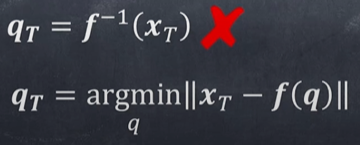

[https://www.youtube.com/watch?v=7XeDkjekmy0](https://www.youtube.com/watch?v=7XeDkjekmy0)

## Diagonalization

### Eigenvalues & Eigenvectors


$$A*v=k*v$$



$$(A-kI)*v=0$$



$$det(A-kI)=0$$



$$k_1=...\quad k_2=...\quad k_3=...$$



$$(A-k)*v=\left[\begin{array}{ccc}
     a_{11}-k_1\quad a_{12}\quad a_{13}  \\
     a_{21\quad }a_{22}-k_2\quad a_{23}  \\
     a_{31}\quad a_{32}\quad a_{33}-k_3
\end{array}\right]*v=0$$


--------------------------------------------------


$$A*P=P*D$$


where: A - input matrix, P - matrix of eigenvectors, D - matrix of eigenvalues

A = [1 0 1; 3 2 7; -3 3/2 0.2]

A =     1.0000         0    1.0000
    3.0000    2.0000    7.0000
   -3.0000    1.5000    0.2000


[P, D] = eig(A)

P =    -0.2283   -0.3765    0.0848
   -0.8523   -0.8312    0.9551
    0.4706    0.4091    0.2840


D =    -1.0614         0         0
         0   -0.0867         0
         0         0    4.3481


AP = A * P

AP =     0.2423    0.0326    0.3688
    0.9047    0.0720    4.1527
   -0.4995   -0.0355    1.2349


PD = P * D  % AP=PD

PD =     0.2423    0.0326    0.3688
    0.9047    0.0720    4.1527
   -0.4995   -0.0355    1.2349


### Diagonalized matrix A


$$A_{diag} = PDP^{-1}$$


A_diag = P*D*inv(P)

A_diag =     1.0000   -0.0000    1.0000
    3.0000    2.0000    7.0000
   -3.0000    1.5000    0.2000


### Matrix to the power of n


$$A^2=(PDP^{-1})(PDP^{-1})=PD^2P^{-1}
$$



$$A^n = PD^{n}P^{-1}$$


D

D =    -1.0614         0         0
         0   -0.0867         0
         0         0    4.3481


D^2

ans =     1.1266         0         0
         0    0.0075         0
         0         0   18.9059


exponentiation = P*D^2*inv(P)

exponentiation =    -2.0000    1.5000    1.2000
  -12.0000   14.5000   18.4000
    0.9000    3.3000    7.5400


exponentiation = A^2

exponentiation =    -2.0000    1.5000    1.2000
  -12.0000   14.5000   18.4000
    0.9000    3.3000    7.5400


## System of linear equations

### Geometrically

Solution can be found geomtrically by finding intersection points/lines/features between all of the objects included in the system of equations.

t = linspace(-10,5,100)

t =   -10.0000   -9.8485   -9.6970   -9.5455   -9.3939   -9.2424   -9.0909   -8.9394   -8.7879   -8.6364   -8.4848   -8.3333   -8.1818   -8.0303   -7.8788   -7.7273   -7.5758   -7.4242   -7.2727   -7.1212   -6.9697   -6.8182   -6.6667   -6.5152   -6.3636   -6.2121   -6.0606   -5.9091   -5.7576   -5.6061   -5.4545   -5.3030   -5.1515   -5.0000   -4.8485   -4.6970   -4.5455   -4.3939   -4.2424   -4.0909   -3.9394   -3.7879   -3.6364   -3.4848   -3.3333   -3.1818   -3.0303   -2.8788   -2.7273   -2.5758


x1 = 5 * t + 3

x1 =   -47.0000  -46.2424  -45.4848  -44.7273  -43.9697  -43.2121  -42.4545  -41.6970  -40.9394  -40.1818  -39.4242  -38.6667  -37.9091  -37.1515  -36.3939  -35.6364  -34.8788  -34.1212  -33.3636  -32.6061  -31.8485  -31.0909  -30.3333  -29.5758  -28.8182  -28.0606  -27.3030  -26.5455  -25.7879  -25.0303  -24.2727  -23.5152  -22.7576  -22.0000  -21.2424  -20.4848  -19.7273  -18.9697  -18.2121  -17.4545  -16.6970  -15.9394  -15.1818  -14.4242  -13.6667  -12.9091  -12.1515  -11.3939  -10.6364   -9.8788


x2 = 4 * t + 4

x2 =   -36.0000  -35.3939  -34.7879  -34.1818  -33.5758  -32.9697  -32.3636  -31.7576  -31.1515  -30.5455  -29.9394  -29.3333  -28.7273  -28.1212  -27.5152  -26.9091  -26.3030  -25.6970  -25.0909  -24.4848  -23.8788  -23.2727  -22.6667  -22.0606  -21.4545  -20.8485  -20.2424  -19.6364  -19.0303  -18.4242  -17.8182  -17.2121  -16.6061  -16.0000  -15.3939  -14.7879  -14.1818  -13.5758  -12.9697  -12.3636  -11.7576  -11.1515  -10.5455   -9.9394   -9.3333   -8.7273   -8.1212   -7.5152   -6.9091   -6.3030


x3 = 2 * t + 6

x3 =   -14.0000  -13.6970  -13.3939  -13.0909  -12.7879  -12.4848  -12.1818  -11.8788  -11.5758  -11.2727  -10.9697  -10.6667  -10.3636  -10.0606   -9.7576   -9.4545   -9.1515   -8.8485   -8.5455   -8.2424   -7.9394   -7.6364   -7.3333   -7.0303   -6.7273   -6.4242   -6.1212   -5.8182   -5.5152   -5.2121   -4.9091   -4.6061   -4.3030   -4.0000   -3.6970   -3.3939   -3.0909   -2.7879   -2.4848   -2.1818   -1.8788   -1.5758   -1.2727   -0.9697   -0.6667   -0.3636   -0.0606    0.2424    0.5455    0.8485


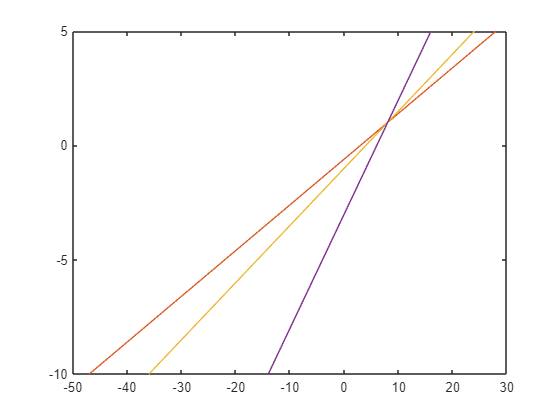

figure(1)
plot(x1, t)
hold on
plot(x2, t)
hold on
plot(x3, t)

### Gaussian-Jordan elimination

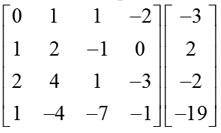

#### Echelon form

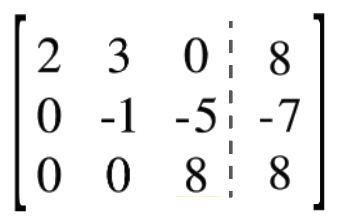

#### Back propagation

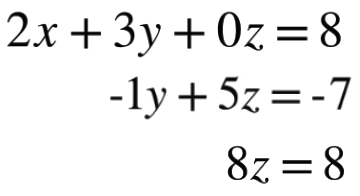

[https://www.chegg.com/homework-help/definitions/gauss-jordan-elimination-method-27](https://www.chegg.com/homework-help/definitions/gauss-jordan-elimination-method-27)

[https://adamdhalla.medium.com/1-3-a-complete-guide-to-gaussian-elimination-dd51f7b4a300](https://adamdhalla.medium.com/1-3-a-complete-guide-to-gaussian-elimination-dd51f7b4a300)

A = [2 1 2 3; 6 2 4 8; 1 -1 0 4; 0 1 -3 -4]

A =      2     1     2     3
     6     2     4     8
     1    -1     0     4
     0     1    -3    -4


A(:, 5) = [5 14 9 -4]'

A =      2     1     2     3     5
     6     2     4     8    14
     1    -1     0     4     9
     0     1    -3    -4    -4


R = rref(A) % solution in the last column

R =      1     0     0     0    -1
     0     1     0     0     2
     0     0     1     0    -2
     0     0     0     1     3


#### Permutation matrices

Used to switch rows when doing Gaussian elimination

A = [2 1 2 3; 6 2 4 8; 1 -1 0 4; 0 1 -3 -4]

A =      2     1     2     3
     6     2     4     8
     1    -1     0     4
     0     1    -3    -4


P = [0 0 1 0; 1 0 0 0; 0 1 0 0; 0 0 0 1]

P =      0     0     1     0
     1     0     0     0
     0     1     0     0
     0     0     0     1


permutation = P*A

permutation =      1    -1     0     4
     2     1     2     3
     6     2     4     8
     0     1    -3    -4


### Inverse method

The most intuitive, simply solve matrix equation for x:


$$Ax=b$$



$$x=A^{-1}b$$


A = [2 1 2 3; 6 2 4 8; 1 -1 0 4; 0 1 -3 -4]

A =      2     1     2     3
     6     2     4     8
     1    -1     0     4
     0     1    -3    -4


b = [5 14 9 -4]'

b =      5
    14
     9
    -4


x = inv(A)*b

x =    -1.0000
    2.0000
   -2.0000
    3.0000


Ax = A * x   % should be the same as b

Ax =     5.0000
   14.0000
    9.0000
   -4.0000


x = A\b

x =    -1.0000
    2.0000
   -2.0000
    3.0000


Ax = A * x

Ax =     5.0000
   14.0000
    9.0000
   -4.0000


What if there is no solution? Moore-Penrose pseudoinverse.


$$\left\{\begin{array}{ll}
x_1+3x_2=17\\5x_1+7x_2=19\\11x_1+13x_2=23
\end{array}$$


A = [1 3; 5 7; 11 13]

A =      1     3
     5     7
    11    13


b = [17, 19, 23]'

b =     17
    19
    23


A_pinv = pinv(A)

A_pinv =    -0.5197   -0.2171    0.2368
    0.4276    0.2039   -0.1316


x = A_pinv*b

x =    -7.5132
    8.1184



$$\left\{\begin{array}{ll}
x_2=\frac{17}{3}-\frac{1}{3}x_1\\
x_2=\frac{19}{7}-\frac{5}{7}x_1\\
x_2=\frac{23}{13}-\frac{11}{23}x_1
\end{array}$$


y1 = 17/3 - 1/3*t

y1 =     9.0000    8.9495    8.8990    8.8485    8.7980    8.7475    8.6970    8.6465    8.5960    8.5455    8.4949    8.4444    8.3939    8.3434    8.2929    8.2424    8.1919    8.1414    8.0909    8.0404    7.9899    7.9394    7.8889    7.8384    7.7879    7.7374    7.6869    7.6364    7.5859    7.5354    7.4848    7.4343    7.3838    7.3333    7.2828    7.2323    7.1818    7.1313    7.0808    7.0303    6.9798    6.9293    6.8788    6.8283    6.7778    6.7273    6.6768    6.6263    6.5758    6.5253


y2 = 19/7 - 5/7*t

y2 =     9.8571    9.7489    9.6407    9.5325    9.4242    9.3160    9.2078    9.0996    8.9913    8.8831    8.7749    8.6667    8.5584    8.4502    8.3420    8.2338    8.1255    8.0173    7.9091    7.8009    7.6926    7.5844    7.4762    7.3680    7.2597    7.1515    7.0433    6.9351    6.8268    6.7186    6.6104    6.5022    6.3939    6.2857    6.1775    6.0693    5.9610    5.8528    5.7446    5.6364    5.5281    5.4199    5.3117    5.2035    5.0952    4.9870    4.8788    4.7706    4.6623    4.5541


y3 = 23/13 - 11/13*t

y3 =    10.2308   10.1026    9.9744    9.8462    9.7179    9.5897    9.4615    9.3333    9.2051    9.0769    8.9487    8.8205    8.6923    8.5641    8.4359    8.3077    8.1795    8.0513    7.9231    7.7949    7.6667    7.5385    7.4103    7.2821    7.1538    7.0256    6.8974    6.7692    6.6410    6.5128    6.3846    6.2564    6.1282    6.0000    5.8718    5.7436    5.6154    5.4872    5.3590    5.2308    5.1026    4.9744    4.8462    4.7179    4.5897    4.4615    4.3333    4.2051    4.0769    3.9487


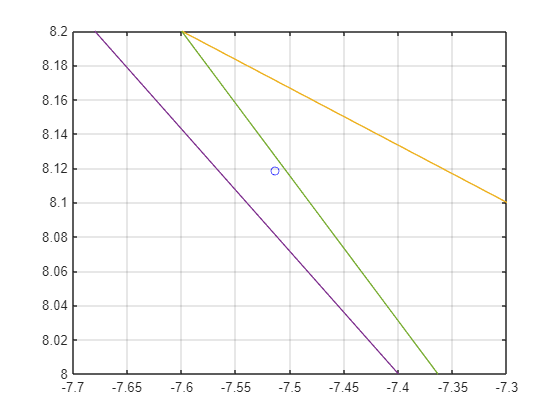


figure(2)
xlim([-7.7 -7.3])
ylim([8 8.2])
plot(t, y1); hold on
plot(t, y2); hold on
plot(t, y3); hold on
plot(x(1), x(2), 'bo')
grid on

The same can be done using the Moore-Penrose pseudoinverse.

### LSQminnorm

Method for computing the minimum-norm least-squares solution of a system of linear equations. Generally more efficient than pinv, also supports square matrices.

x = lsqminnorm(A,b)

x =    -7.5132
    8.1184


### Cramer's rule


$$Ax=b$$



$$x_1=\frac{det(A_{x_1})}{det(A)}$$



$$x_2=\frac{det(A_{x_2})}{det(A)}$$


...

A = [2 1 2 3; 6 2 4 8; 1 -1 0 4; 0 1 -3 -4]

A =      2     1     2     3
     6     2     4     8
     1    -1     0     4
     0     1    -3    -4


b = [5 14 9 -4]'

b =      5
    14
     9
    -4



Ax1 = A; Ax1(:,1) = b

Ax1 =      5     1     2     3
    14     2     4     8
     9    -1     0     4
    -4     1    -3    -4


Ax2 = A; Ax2(:,2) = b

Ax2 =      2     5     2     3
     6    14     4     8
     1     9     0     4
     0    -4    -3    -4


Ax3 = A; Ax3(:,3) = b

Ax3 =      2     1     5     3
     6     2    14     8
     1    -1     9     4
     0     1    -4    -4


Ax4 = A; Ax4(:,4) = b

Ax4 =      2     1     2     5
     6     2     4    14
     1    -1     0     9
     0     1    -3    -4



x(1) = det(Ax1)/det(A);
x(2) = det(Ax2)/det(A);
x(3) = det(Ax3)/det(A);
x(4) = det(Ax4)/det(A)

x =    -1.0000
    2.0000
   -2.0000
    3.0000



A * x   % should be the same as b

ans =     5.0000
   14.0000
    9.0000
   -4.0000


### LU method

LU decomposition - lu() function return matrices L (lower triangular matrix), U (upper triangular matrix) and P (permutation matrix)


$$Ax=b\qquad ,A=LU$$
 


$$LUx=b$$



$$Ux=L^{-1}b$$



$$x = U^{-1}L^{-1}b$$


This method is better when considering complexity, comparing to other exact methods + it's economical in terms of memory management. It's easy to invert triangular matrices and solve systems of linear equations using only forward and back propagation and no Gaussian elimination.

[L, U] = lu(A)

L =     0.3333   -0.2500   -0.1429    1.0000
    1.0000         0         0         0
    0.1667    1.0000         0         0
         0   -0.7500    1.0000         0


U =     6.0000    2.0000    4.0000    8.0000
         0   -1.3333   -0.6667    2.6667
         0         0   -3.5000   -2.0000
         0         0         0    0.7143


x = inv(U)*inv(L)*b

x =    -1.0000
    2.0000
   -2.0000
    3.0000


A * x   % should be the same as b

ans =     5.0000
   14.0000
    9.0000
   -4.0000


## SVD

SVD is a method that decomposes a matrix into 3 other matrices


$$A=UEV^T$$


where U, V are orthogonal, E is diagonal

One could say it's a substitution of diagonalization for non-square matrices.

A = [1 0 1 2 1; -3 -3.2 0.2 5 1; 5 3 2 -1 0]

A =     1.0000         0    1.0000    2.0000    1.0000
   -3.0000   -3.2000    0.2000    5.0000    1.0000
    5.0000    3.0000    2.0000   -1.0000         0



[U,E,V] = svd(A)

U =    -0.0436    0.5887    0.8072
   -0.7478    0.5165   -0.4171
    0.6625    0.6218   -0.4177


E =     8.4634         0         0         0         0
         0    4.4132         0         0         0
         0         0    0.4184         0         0


V =     0.6513    0.4867   -0.0712   -0.3791   -0.4361
    0.5176    0.0481    0.1955    0.8282    0.0749
    0.1337    0.4386   -0.2668   -0.1219    0.8389
   -0.5304    0.7111   -0.1283    0.3455   -0.2778
   -0.0935    0.2504    0.9322   -0.1900    0.1528


U*E*V'

ans =     1.0000    0.0000    1.0000    2.0000    1.0000
   -3.0000   -3.2000    0.2000    5.0000    1.0000
    5.0000    3.0000    2.0000   -1.0000    0.0000


Examples of use: data size reduction.

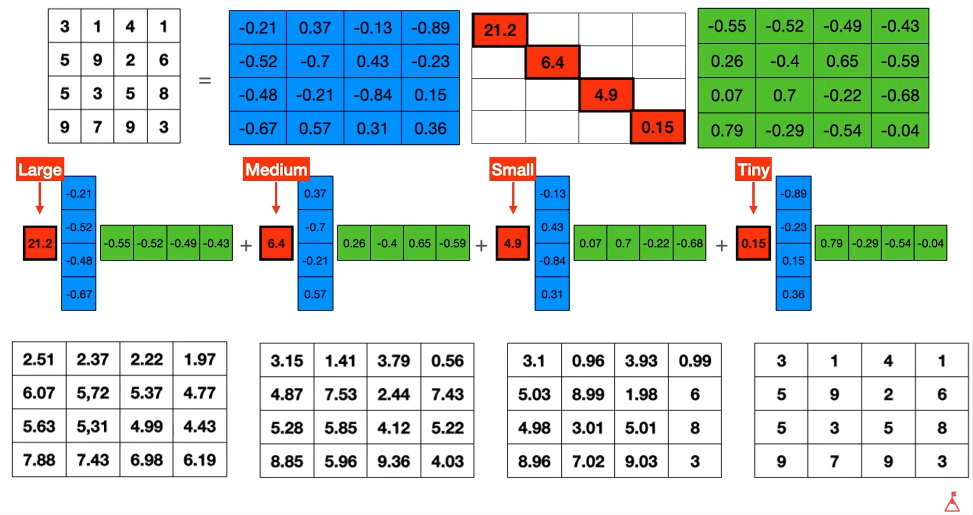

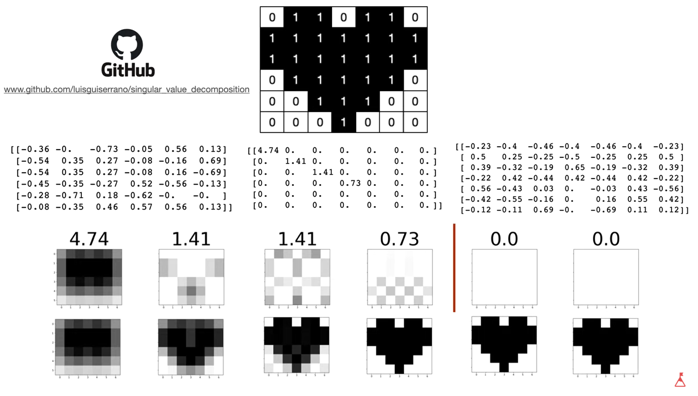

[https://www.youtube.com/watch?v=DG7YTlGnCEo](https://www.youtube.com/watch?v=DG7YTlGnCEo)

## Transformations

### Rotation

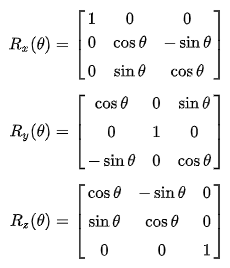

v1 = [5, 0, 2]'

v1 =      5
     0
     2


Rx_90 = [1 0 0; 0 0 -1; 0 1 0]

Rx_90 =      1     0     0
     0     0    -1
     0     1     0


Rz_90 = [0 -1 0; 1 0 0; 0 0 1]

Rz_90 =      0    -1     0
     1     0     0
     0     0     1


v1_r_90 = Rx_90*v1

v1_r_90 =      5
    -2
     0


v1_r_180 = Rz_90*v1

v1_r_180 =      0
     5
     2


x_1 = [0, v1(1)]

x_1 =      0     5


y_1 = [0, v1(2)]

y_1 =      0     0


z_1 = [0, v1(3)]

z_1 =      0     2


x_2 = [0, v1_r_90(1)]

x_2 =      0     5


y_2 = [0, v1_r_90(2)]

y_2 =      0    -2


z_2 = [0, v1_r_90(3)]

z_2 =      0     0


x_3 = [0, v1_r_180(1)]

x_3 =      0     0


y_3 = [0, v1_r_180(2)]

y_3 =      0     5


z_3 = [0, v1_r_180(3)]

z_3 =      0     2


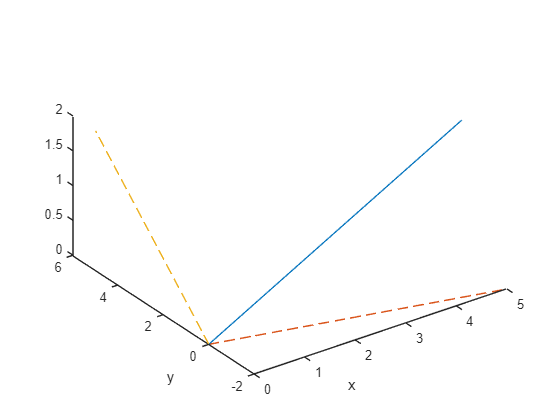

figure(3)
plot3(x_1, y_1, z_1)
hold on
plot3(x_2, y_2, z_2, '--')
hold on
plot3(x_3, y_3, z_3, '--')
hold on
xlabel('x')
ylabel('y')